# Modelowanie urządzenia hamującego lądujący samolot

#### Mateusz Wójcik, 6.11.2024

## **Cel ćwiczenia:**

Celem poniższego ćwiczenia jest implementacja modelu urządzenia hamującego samolot w środowisku SIMULINK, bazując na podanym w konspekcie modelu matematycznym. W czasie realizacji zadania wystąpi konieczność zapoznania się z zasadą działania nowego bloku pozwalającego interpolować funkcję na podstawie tabeli punktów.

## Część teoretyczna

Model hamownika jest reprezentowany przez następujacy schemat:

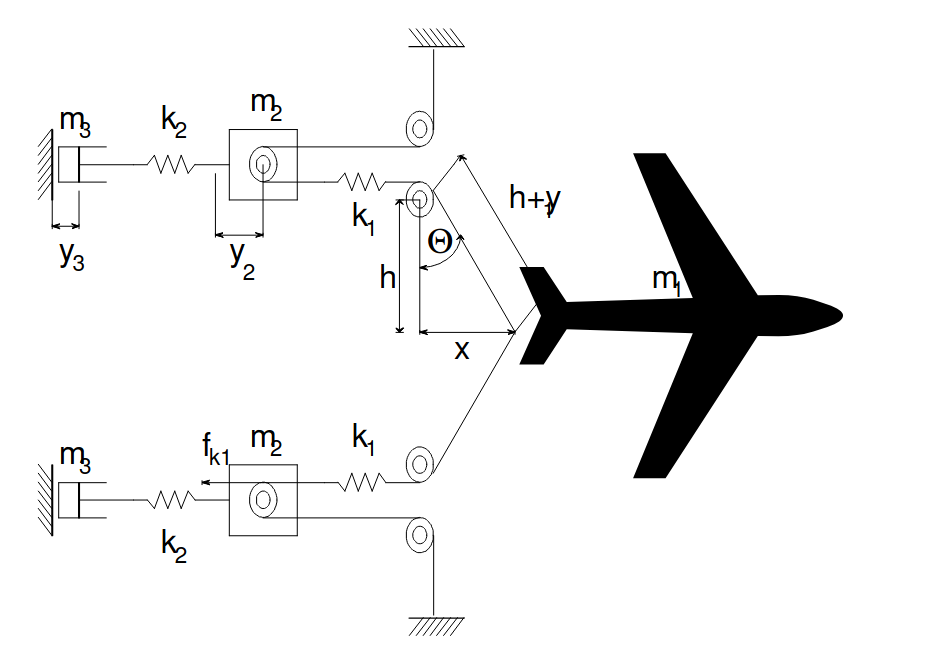

Można zauważyć, że instalacja składa się z dwóch symetrycznych części. Można zatem skorzystać z dwóch podejść, albo założyc, że elementy są idealnie symetrycznei w ostateczności wyniki pomnożyć przez dwa, albo uwzględnić w swoim modelu możliwość odchyłek, tzn. różnica w współczynnikach sprężystości poszczególnych elementów, czy mas. W zaproponowanym rozwiązaniu skorzystano z drugiej opcji pozwalając na badanie różnych przypadków, zmieniając jedynie zmienne zdefiniowane w tym skrypcie.

W celu ułatwienia analizy i tworzenia układu, modelowanie podzielono na trzy części, wraz z każdą zwiększając dokładność odwzorowania problemu. Analizę rozpoczęto od prostego modelu:

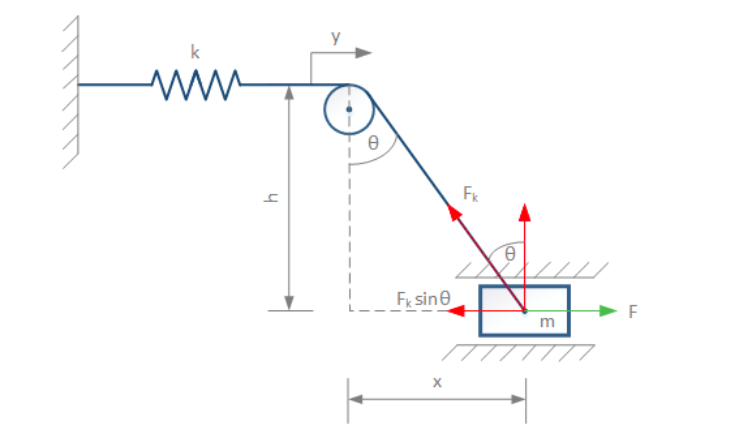

Model składa się z masy, która może pouszać się jedynie poziomo i połączonej za pomocą bloczka ze sprężyną. Dla powyższego układu jesteśmy w stanie napisać równanie:

$m\ddot{x} = -F_k sin\theta$,

które po uwzględnieniu zależności trygonometrycznych można przekształcić do postaci:

$m\ddot{x} = -k \left (\sqrt{h^2 +x^2} - h \right) \frac{x}{\sqrt{h^2 + x^2}}
$,

W dalszej części skomplikowano układ rozważając model z bloczkiem przesuwnym:

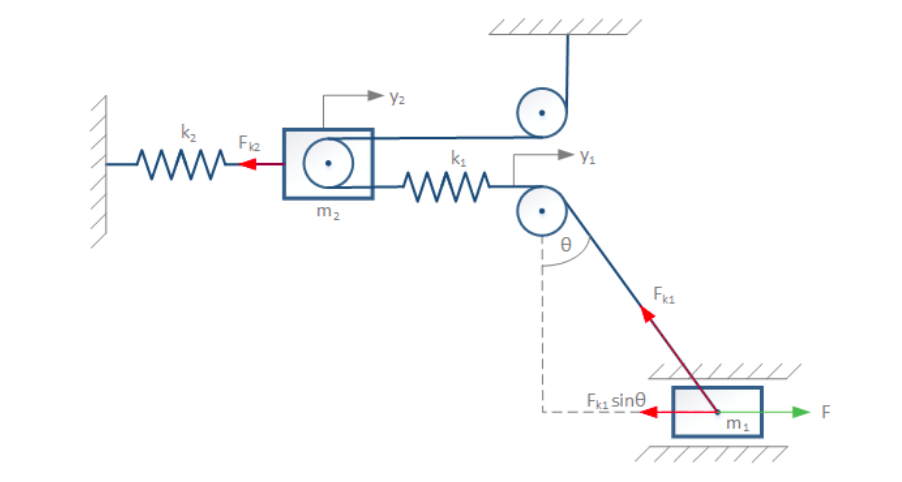

Na podstawie schematu zapisano równanie siły działającej na sprężynę $k_1$:


$$F_{k1} = 
\begin{cases} 
      k_1 (y_1 - 2y_2), & y_1 \geq 2y_2 \\
      0, & y_1 < 2y_2 
\end{cases}
$$


Zatem po modyfikacji wcześniejszego równania otrzymujemy:

$m_1
\ddot{x} = -F_{k1}\frac{x}{\sqrt{h^2 + x^2}}
$,

Jednak rozważając ten model musimy jeszcze napisać równanie opisujące zmienną $y_2$:

$m_2\ddot{y}_2 = -k_2 y_2 + 2 F_{k1}$.

Ostatnim brakujący elementem jest tłumik, który pozwoli na otrzymanie efektywnego hamowania, bez generacji przyspieszeń zagrażających życiu pilota. Ostateczny układ można przedstawić w postaci schematu poniżej: 

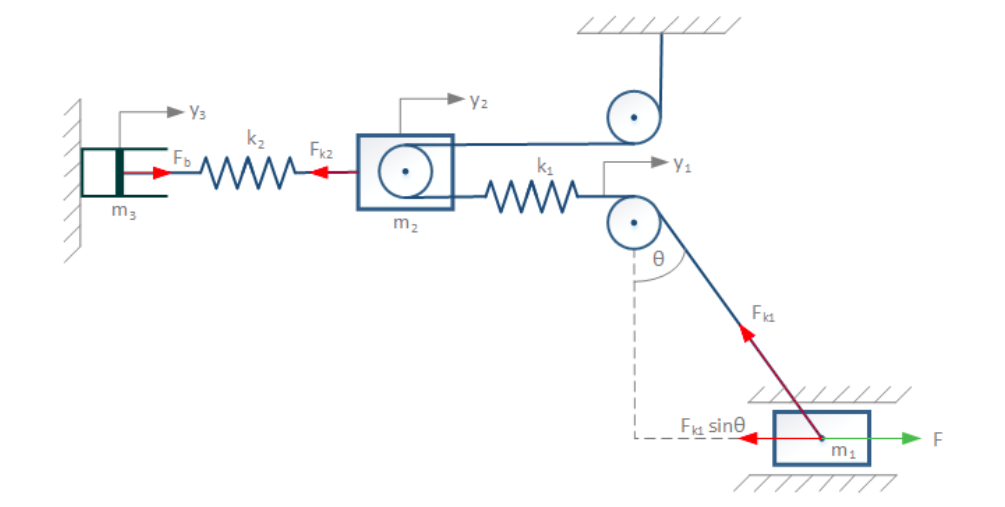

W ostatecznym modelu równanie ruchu masy $m_1$ pozostaje bez zmian:

$m_1
\ddot{x} = -F_{k1}\frac{x}{\sqrt{h^2 + x^2}}
$,

gdzie:


$$F_{k1} = 
\begin{cases} 
      k_1 (y_1 - 2y_2), & y_1 \geq 2y_2 \\
      0, & y_1 < 2y_2 
\end{cases}
$$


Równanie ruchu masy $m_2$ przyjmuje za to postać:

$m_2\ddot{y}_2 = 2 F_{k1} - F_{k2}$,

gdzie:


$$F_{k2} = 
\begin{cases} 
      k_2 (y_2 - y_3), & y_2 \geq y_3 \\
      0, & y_2 < y_3 
\end{cases}
$$


Aby opisać kolejną ruchomą masę dodaną do układu należy ułożyć jeszcze jedno równanie:

$m_3\ddot{y}_3 = F_{k2} - F_b$,

gdzie $F_b$ jest nieliniowa i wyraża się zależnością:

$F_b = f(y_3)\dot{y}_3$,

a funkcja $f(y_3)$ zostałą zweryfikowana doświadczalnie i przedstawiona w postaci danych tabelarycznych przedstawionych w konspekcie.

## Implementacja w Simulinku

Posiadając wszelkie niezbędne zależności przystąpiono do tworzenia modelu w środowisku Simulink. Etap rozpoczęto od zdefiniowania stałych i zamiany jednostek na jednostki układu SI.

### Definiowanie zmiennych

m1=14000;     %kg
m21=450.28;    %kg
m22=450.28;   %kg
m31=200;     %kg
m32=200;       %kg
K1=54.7;      %kN/m
K2=303.6;     %kN/m
h=42;         %m
k11 = K1 * 1000;
k12 = K1 * 1000;
k21 = K2 * 1000;
k22 = K2 * 1000;

### Model w Simulinku

Tworząc model skorzystano z tworzenia subsystemów, w celu zmniejszenia komplikacji wizualnej modelu oraz możliwości łatwej duplikacji kodu zmieniając dane opisujące poszczególną stronę hamownika. W celu odróżnienia od siebie poszczególnych sekcji hamownika użyto formatowania kolorami:

- jasnoniebieski - integratory opisujące zachowanie zmiennej x,

- ciemnonibieski - pierwsza część ćwiczenia, elementy najprostszego modelu,

- fioletowy - części reprezentujący bloczek ruchomy,

- biały -  podukład reprezentujący działanie tłumika.

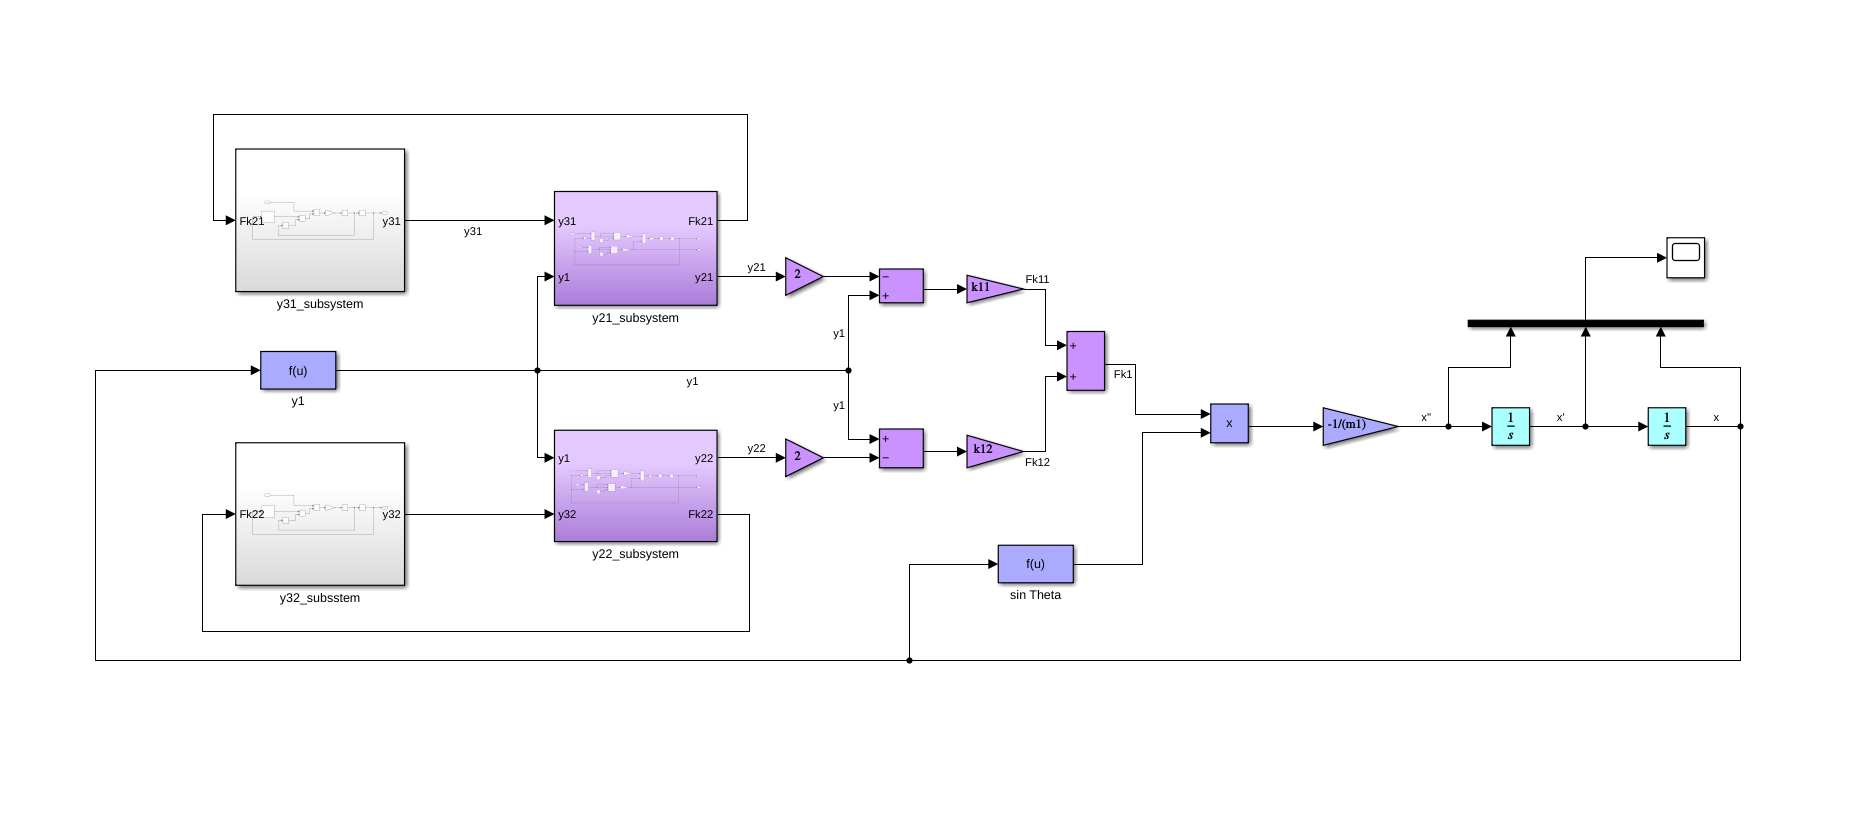

Podczas tworzenia modelu zastała potrzeba wykonywania różnych operacji matematycznych. W celu otrzymania mnożenia ze sobą odpowienidch sygnałów użyto oferowanego przez środowisko Simulink bloczku **Product. ** Oprócz tego dla bardziej złożonych funkcji, jak np. dla tej reprezentującej $sin \theta$, skorzystano z bloku **Fcn,** który pozwala na zdefiniowanie wewnątrz jego struktury, własnej funkcji matematycznej, nawet z uwzględnieniem zmiennych zdefiniowanych w skrypcie. Do załączania kolejnych funkcji $F_{k1}$ i $F_{k2}$ użyto natomiast bloku **Switch**.

Poniżej przedstawiono strukturę y_21 subsystem. Blok y_22_subsystem jest analogicznie zbudowany, z tą jedynie różnicą, że drugi indeks w stałych jest zamieniony $1 \rightarrow 2$.

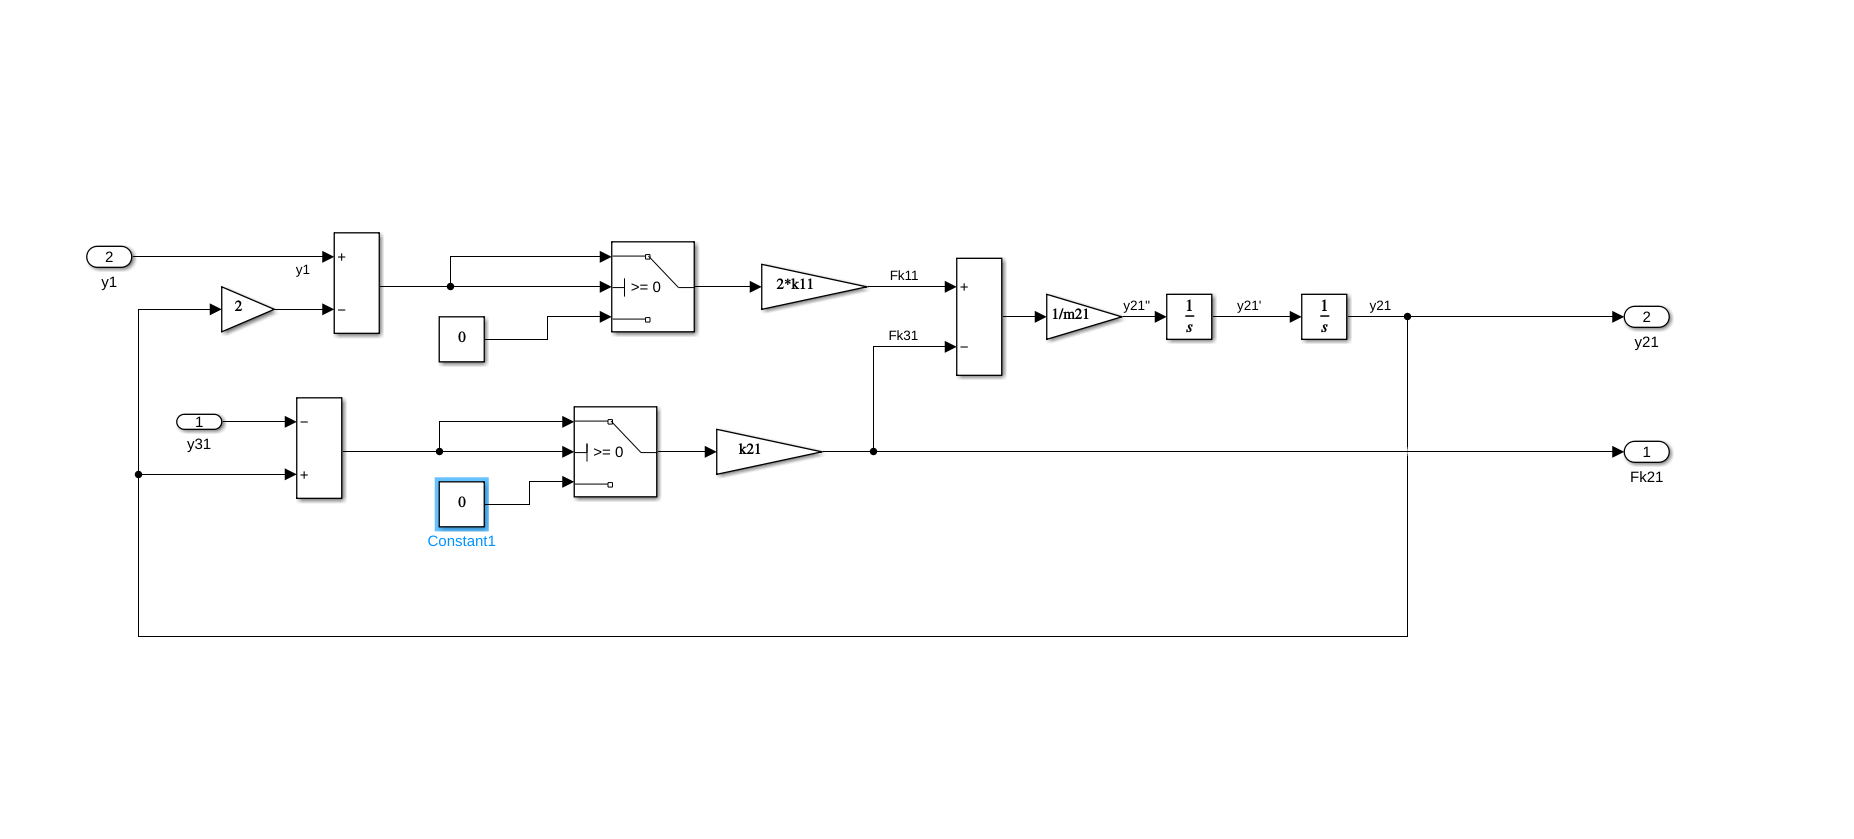

Struktura y_31_subsystem zostało przedstawiono poniżej. Jednym z kluczowych jej elementów jest blok **1-D Lookup Table**, który pozwala wygenerować na podstawie podanych punktów przebieg funkcji opisującej charakterysykę zastosowanego w urządzeniu tłumika. Następnie, podczas symulacji gdy podawana jest na wejście określona wartość sygnału to ten bloczek na jej podstawie i na podstawie wygenerowanego przebiegu funkcji wystawia na swoje wyjście odpowiednią odpowiedź.

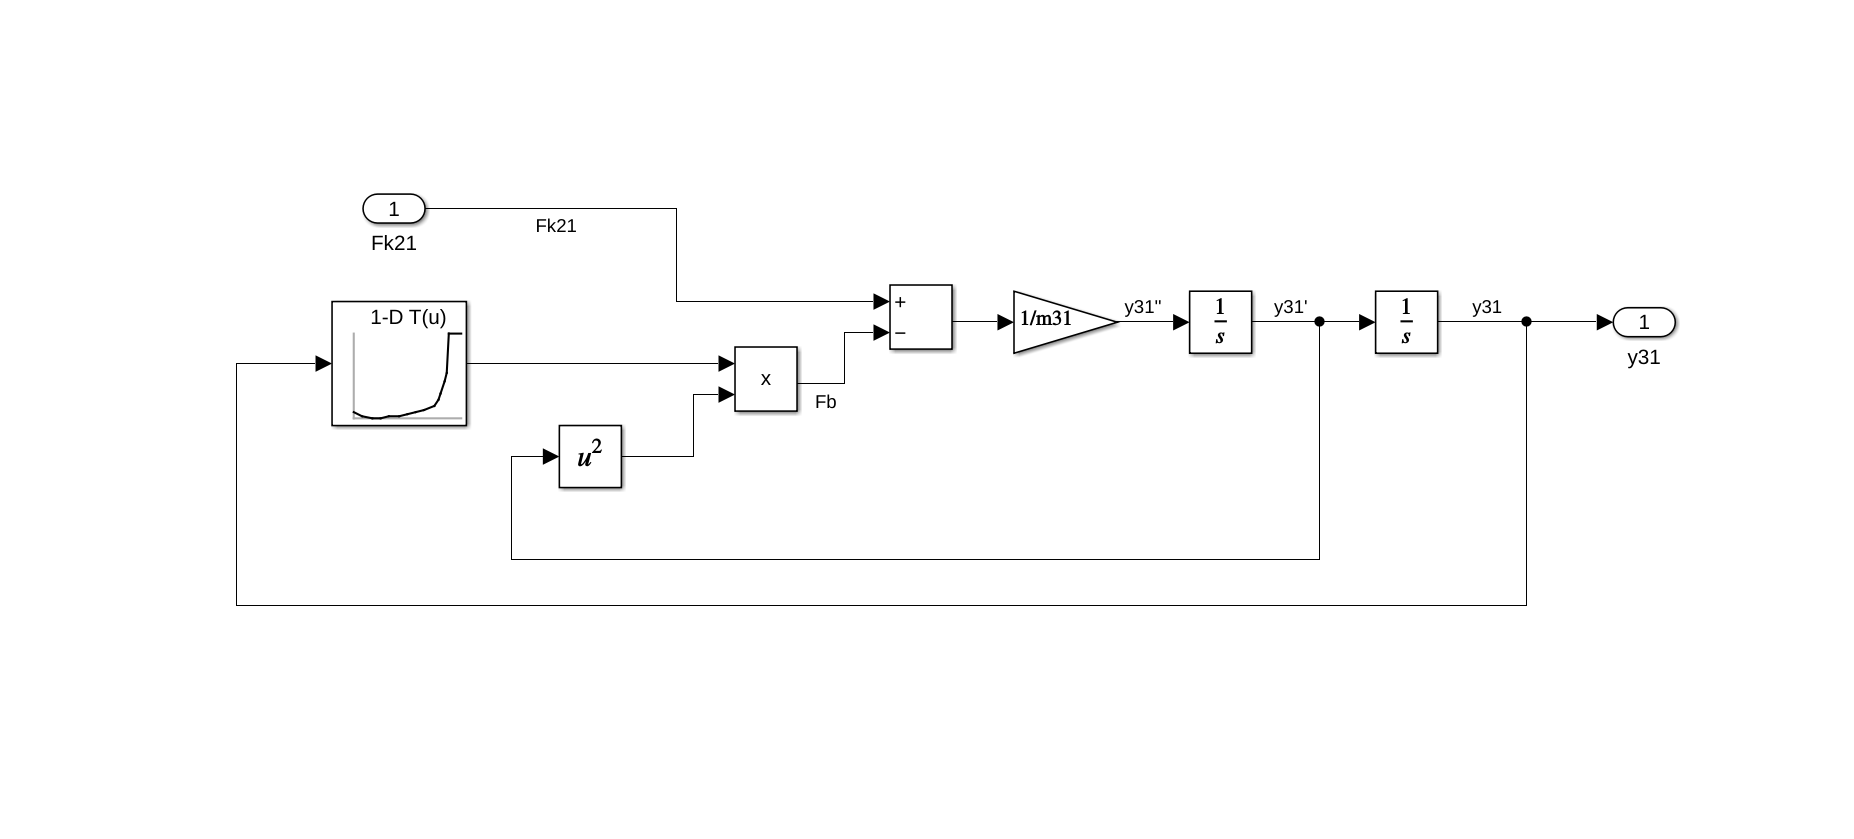

Konfiguracja bloku 1 -D Lookup Table, wraz z zdefiniowanymi już punktami i wygenerowanym wykresem, została przedsawiona na rysunku poniżej:

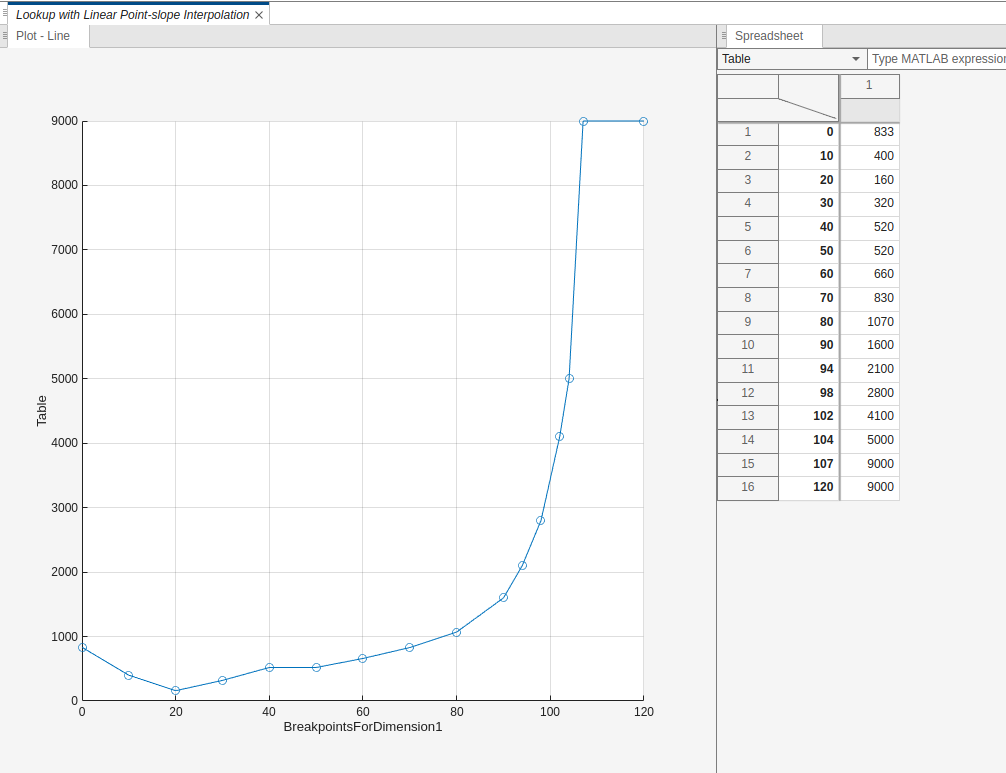

Wszystkie omówione dotychczas elementy pozwalają na wykonanie odpowiednich obliczeń numerycznych w środowisku SIMULINK, pozwalającego uzyskać wyniki dla symulowanego modelu.

### Wyniki symulacji

Na podstwie zbudowanego modelu przeprowadzono symulacje, której wyniki zobrazowano na poniższych wykresach:

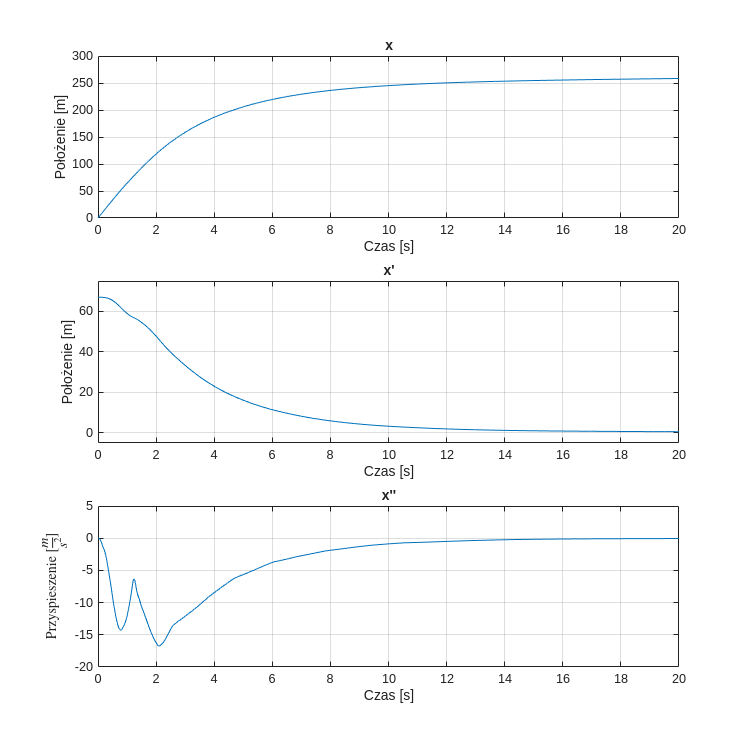

figure("Position",[100 100 1000 1000])
subplot(311);
plot(out.tout, out.x{1}.Values.Data(:,3))
title("x")
xlabel("Czas [s]")
ylabel("Położenie [m]")
grid on

subplot(312);
plot(out.tout, out.x{1}.Values.Data(:,2))
title("x'")
xlabel("Czas [s]")
ylabel("Położenie [m]")
grid on
axis([0 20 -5 75])

subplot(313);
plot(out.tout, out.x{1}.Values.Data(:,1))
title("x''")
ylabel("Przyspieszenie $[\frac{m}{s^2}]$", Interpreter="latex")
grid on
axis([0 20 -20 5])
xlabel("Czas [s]")

W wyniku symulacji otrzymano trzy wykresy, gdzie kolejno przedstawiono zależność:

- Przemieszczenia samolotu w funkcji czasu,

- Prędości samolotu w funkcji czasu,

- Działającego na samolot przyspieszenia w funkcji czasu.

Analizując powyższe charakterystyki zauważono, że odległość hamowania samolotu z wykorzystaniem samego hamownika (nigdzie nie uwzględnialiśmy sily pochodzącej od hamowania przez pilota) wynosi około 250 m. Jest to realny wynik, który można poprawić używająć dodatkowej siły. Mimo wszystko, należy zwrócić uwagę ma wykres przedstawiający działające na samolot przyspieszenie. Jego wartość nie przekracza 2g, zatem hamownik zapewnia dla pilota również przeciążenia, które jest w stanie po odpowiednim przeszkoleniu wytrzymywać bez większych problemów. Można, więc stwierdzić, że układ o podanych parametrach dobrze spełnia swoje zadanie.

## Wnioski

Posdczas zajęć zapoznno się z sposobem rozwiązywania złożonych modeli matematycznych. Szczególnie ważną umiejętnością jest tworzenie prostych modeli, a następnie systematycznie je udoskonalanie, dodając kolejne obiekty, pozwalające na lepsze odwzorowanie rzeczywistości. Jest to umiejętność, na którą zazwyczaj nie istnieje jeden idealny przepis, dlatego każdy przykład jest zawsze wartościowy, ponieważ pozwala rozbudowywać własną intuicję w tym obszarze. Szczególnie wartościowe jest, że temat zajęć dotyczy interesujących obiektów fizycznych, które mają zastosowanie w rzeczywistości, a  nie tylko akademickich przykładów. Składa się to na to, że zadania wykonuje się z ciekawością i chęcią przetestowania innych danych wejściowych, aby głębiej poznać dany temat.